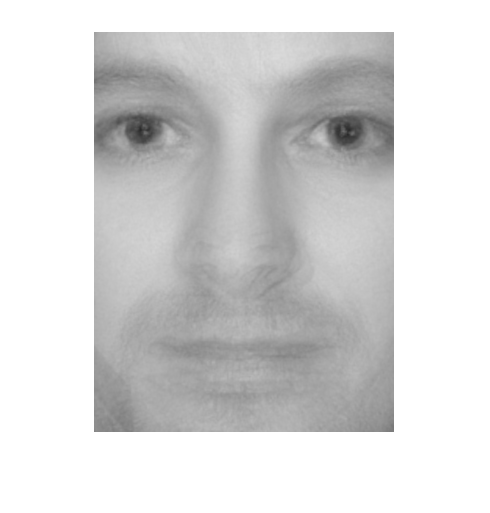

Settings
images = dir("../DB1/*.jpg");
X = zeros(NORMALIZED_FACE_HEIGHT * NORMALIZED_FACE_WIDTH, length(images));
for i = 1:length(images)
img = imread("../DB1/" + images(i).name);
%imshow(img);
img = colorCorrection(img);
imgD = im2double(img);
%Normalize the face
eyeCoords=findEyeCoordinates(img);
%Eyes according to our viewpoint, eyeL is the person's right eye.
eyeL = eyeCoords(1, :);
eyeR = eyeCoords(2, :);
normalface = normalizeFace(eyeL, eyeR, imgD);
%imshow(normalface);

image = rgb2gray(normalface);
%imshow(image);
[height, width] = size(image);
x = reshape(image, height * width, 1);

X(:,i) = x; %face vector
end

%create avg face 
avgFace = 1 / length(images) * sum(X,2); %mu
imshow(reshape(avgFace, height, width));

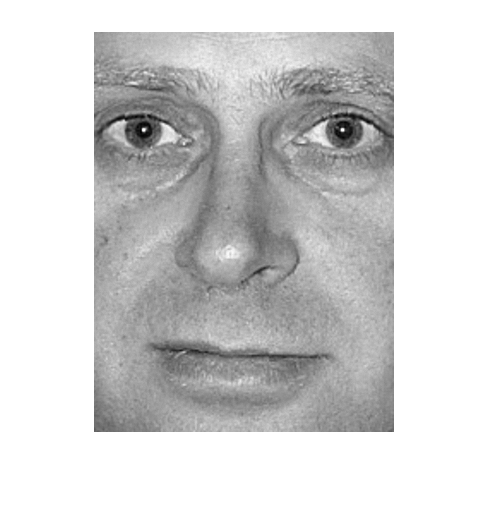


diffFace = X - avgFace; %A where each col is phi = xi - mu

%C = diffFace' * diffFace; %16x16 matrix of eigenvectors

[eVector, eValues] = eig(diffFace' * diffFace);
%sort eigen values in descending order
[eValues, order] = sort(diag(eValues),'descend');

%compute eigen-faces
ui = diffFace * eVector;
ui = ui(:,order);

for i = 1:size(ui,2)
    ui(:,i) = ui(:,i) / norm(ui(:,i));
end

s = zeros(size(ui, 1), 1);

weights = ui' * diffFace;

%Reconstruct face 
for i = 1:16 % amount of weights to use
    s = s +  weights(i, 1) * ui(:,i);
end

L1 = avgFace + s;

imshow(reshape(L1, height, width),[]);

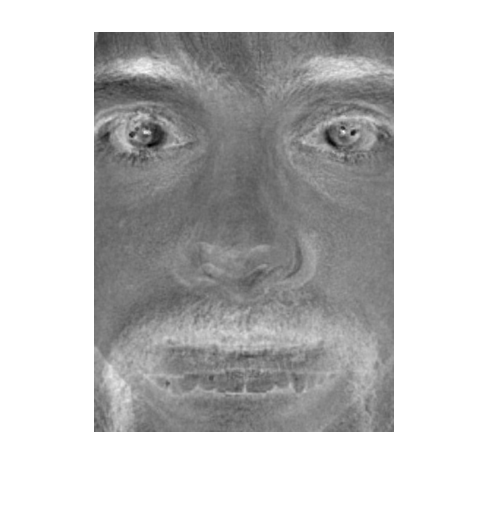


%EigenFaces = diffFace * C; %find the largest eigenvectors u_i of the n x n matrix AA^t 

%weights = EigenFaces' * diffFace;

imshow(reshape(ui(:,3), height, width), []);